# **Computation Vision - Project 2 Report**

**Topic A3:   People and Vehicle Detection using Thermal Imagery**

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## 1. Introduction

With the rapid advancement of autonomous driving and Advanced Driver-Assistance Systems (ADAS), the ability to reliably detect pedestrians and vehicles in real-time has become a fundamental requirement for safe road navigation. Traditional RGB-based vision systems, while effective under standard conditions, are inherently limited by their dependence on visible light, making them prone to failure in challenging environments such as darkness, fog, heavy rain, or glare which are precisely the conditions where robust perception is most critical for the safety of both passengers and other road users.

Thermal imaging offers a compelling alternative, as it captures heat signatures emitted naturally by humans and vehicles rather than relying on reflected light. This makes thermal-based detection largely invariant to lighting conditions, providing a more consistent and reliable perception pipeline for safety-critical applications. Unlike RGB cameras, thermal sensors detect temperature differences between objects and their surroundings, preserving the distinct silhouettes of pedestrians and vehicles even in the most adverse scenarios. These properties make thermal sensors an increasingly attractive complement to visible-light cameras in modern ADAS systems.

As part of Topic A3 of the Intelligent Vision Systems course, this project aims to develop and optimize a deep learning-based object detection model using the FLIR ADAS dataset. The goal is to build a system capable of accurately detecting pedestrians and vehicles in real driving scenarios. Specifically, this report details the following steps:

- **Dataset Analysis and Preparation:** Characterization of the FLIR ADAS thermal dataset, identification of relevant object classes, and the structuring of data for training, validation, and testing;

- **Baseline Model:** The design and deployment of an initial object detection pipeline using simple Deep Learning Architecture from what we will improve on;

- **Model Evaluation:** Rigorous training and assessment of the baseline model using standard computer vision metrics to analyze its initial detection capabilities;

- **System Optimization:** Iterative improvement of the detection system through the exploration of advanced architectures, hyperparameter tuning, targeted preprocessing, and data augmentation strategies.

This project explores the development and optimization of a deep learning-based object detection system, demonstrating how careful dataset preparation, model design, and iterative improvement can enhance detection performance, ultimately contributing to safer autonomous navigation.

It is important to note that the FLIR ADAS dataset is approximately 11 GB in size. Due to this large volume, it cannot be included directly with the project files. To run the live scripts and replicate the results, it is necessary to download the dataset from the official source before executing any data processing or training steps.

**Attention**: In order to reduce clutter in the report, auxiliary scripts (specifically those implemented for subsequent processing steps and for plotting purposes) have been organized into separate files and are only referenced in the code when invoked. Auxiliary functions follow the naming convention `aux_<function>.m`, while plotting functions follow `plot_<function>.m`.

## 2. Dataset Analysis and Preparation

### 2.1 Dataset Overview

Thermal imaging captures the heat emitted by objects rather than the visible light reflected from them. In the context of autonomous driving and ADAS, this property allows thermal sensors to reliably detect pedestrians and vehicles even under poor lighting conditions such as nighttime, fog, or glare. Unlike RGB cameras, which are sensitive to color and brightness variations, thermal cameras produce grayscale images where the intensity represents the temperature of each pixel. This makes thermal images particularly useful for detecting humans and vehicles as warm objects against cooler backgrounds, though they often lack the detailed textures and color cues present in standard RGB images.

To get an intuitive understanding of thermal imagery, Figure 1 presents an example thermal image from the FLIR ADAS dataset alongside a corresponding RGB image captured from a similar scene (note that the images are not from the same frame and scene but are selected to give a visual comparison).

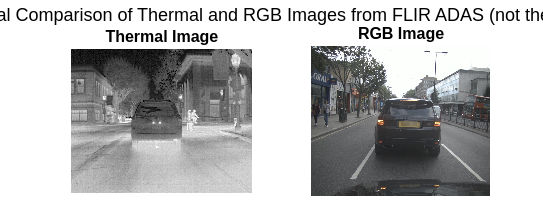

% Paths to example images
thermalPath = './Data/Compare_rgb_vs_thermal/image_THERMAL.jpg';
rgbPath     = './Data/Compare_rgb_vs_thermal/image_RGB.jpg';

% Read images
imgThermal = imread(thermalPath);
imgRGB     = imread(rgbPath);

% Ensure thermal is single-channel
if size(imgThermal,3) > 1
    imgThermal = rgb2gray(imgThermal);
end

% Display side by side
figure('Name','Thermal vs RGB Comparison','Position',[100 100 1000 400]);

subplot(1,2,1);
imshow(imgThermal);
title('Thermal Image','FontSize',12);

subplot(1,2,2);
imshow(imgRGB);
title('RGB Image','FontSize',12);

sgtitle('Figure 1: Visual Comparison of Thermal and RGB Images from FLIR ADAS (not the same scene)','FontSize',14);

Before designing and training the object detection architecture, it is essential to understand the underlying data distribution. The FLIR ADAS dataset provides annotations in the standard MS-COCO JSON format [1] and is pre-divided into three dedicated splits: Training, Validation, and Testing. Each split is stored in a separate folder and contains a `coco.json` file with the corresponding image metadata and bounding box annotations. The script below loads each split, parses the COCO annotations, and computes the number of images per split along with their relative proportions. The resulting distribution is summarised in Table 1.

[1] TELEDYNE | FLIR OEM Documentation: [https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/](https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/)

%% Define Dataset Paths and Splits
datasetPaths = {'./Data/images_thermal_train', './Data/images_thermal_val', './Data/video_thermal_test'};
splitNames = {'Train', 'Validation', 'Test'};

%% Read Categories from the Training Dataset
cocoPath = fullfile(datasetPaths{1}, 'coco.json');
cocoData = jsondecode(fileread(cocoPath)); 

numClasses = length(cocoData.categories); 
classNames = strings(1, numClasses);
classIDs = zeros(1, numClasses);

for i = 1:numClasses
    classNames(i) = cocoData.categories(i).name;
    classIDs(i) = cocoData.categories(i).id;
end

numImagesPerSplit = zeros(1, length(datasetPaths));
countsPerSplit = zeros(numClasses, length(datasetPaths));

%% Process Each Dataset Split
for d = 1:length(datasetPaths)
    cocoPath = fullfile(datasetPaths{d}, 'coco.json');    
    cocoData = jsondecode(fileread(cocoPath)); 
    
    numImagesPerSplit(d) = length(cocoData.images);
    
    if d == 1
        numImgs   = length(cocoData.images);
        filenames   = cell(numImgs, 1);
        peopleBoxes  = cell(numImgs, 1);
        vehicleBoxes = cell(numImgs, 1);

        imageIDList = zeros(numImgs, 1);
        for k = 1:numImgs
            filenames{k}   = fullfile(datasetPaths{1}, cocoData.images(k).file_name);
            imageIDList(k) = cocoData.images(k).id;
        end
    end

    lowerClassNames = lower(classNames);
    targetClass1 = "person";
    targetClass2 = ["car", "motorcycle", "bus", "train", "truck", "other vehicle"];

    annotations = cocoData.annotations;
    for i = 1:length(annotations)
        if iscell(annotations)
            ann = annotations{i};
        else
            ann = annotations(i);
        end
        
        idx = find(classIDs == ann.category_id);
        if ~isempty(idx)
            countsPerSplit(idx, d) = countsPerSplit(idx, d) + 1;
        end

        % Store bounding boxes for train split visualization
        if d == 1
            catName = lower(classNames(idx));
            imgIdx  = find(imageIDList == ann.image_id, 1);
            bbox    = ann.bbox; % [x, y, w, h]

            if catName == targetClass1
                peopleBoxes{imgIdx} = [peopleBoxes{imgIdx}; bbox];
            elseif any(catName == targetClass2)
                vehicleBoxes{imgIdx} = [vehicleBoxes{imgIdx}; bbox];
            end
        end
    end
end

% Number and Percentage of Images per Split
totalImages = sum(numImagesPerSplit);

pcts = arrayfun(@(x) sprintf('%.2f%%', (x/totalImages)*100), numImagesPerSplit, 'UniformOutput', false);

T_splits = table(splitNames', numImagesPerSplit', pcts', ...
    'VariableNames', {'Split', 'N_Images', 'Percentage'});

disp('Table 1: Image Count and Percentage by Dataset Split');

Table 1: Image Count and Percentage by Dataset Split


disp(T_splits);

        Split         N_Images    Percentage
    ______________    ________    __________

    {'Train'     }     10742      {'68.70%'}
    {'Validation'}      1144      {'7.32%' }
    {'Test'      }      3749      {'23.98%'}



Based on the script's output, the data distribution is:

- Training Set: 10,742 images (68.70%)

- Validation Set: 1,144 images (7.32%)

- Testing Set: 3,749 images (23.98%)

This distribution follows standard deep learning practice, allocating the majority of the data to training while reserving a substantial portion for final evaluation. The test set, comprising approximately 24% of the total data, provides a sufficiently large and unseen sample to produce reliable performance estimates. The validation set, although smaller, is used exclusively during training to monitor generalisation and guide hyperparameter tuning.

### 2.2 Category Analysis

The FLIR ADAS dataset originally contains a large number of annotated categories, however many of these have zero instances across all splits and are therefore disregarded. Table 2 presents only the 16 categories that have at least one annotated instance in the dataset.

% Full Category Table (all classes in dataset)
validIdx = any(countsPerSplit > 0, 2);  % categories with at least 1 instance

T_categories = table(...
    classNames(validIdx)', ...
    classIDs(validIdx)', ...
    countsPerSplit(validIdx, 1), ...
    countsPerSplit(validIdx, 2), ...
    countsPerSplit(validIdx, 3), ...
    'VariableNames', {'Category', 'ID', 'Train', 'Val', 'Test'});

disp('Table 2: All Categories with Non-Zero Instance Counts');

Table 2: All Categories with Non-Zero Instance Counts


disp(T_categories);

       Category        ID    Train    Val     Test 
    _______________    __    _____    ____    _____

    "person"            1    50478    4470    12323
    "bike"              2     7237     170      113
    "car"               3    73623    7133    30517
    "motor"             4     1116      55     3314
    "bus"               6     2245     179        0
    "train"             7        5       0        0
    "truck"             8      829      46     2634
    "light"            10    16198    2005     6758
    "hydrant"          11     1095      94      277
    "sign"             12    20770    2472     5660
    "dog"              17        4       0       25
    "deer"             18        8       0        0
    "skateboard"       37       29       3        0
    "stroller"         73       15       6       

As shown in Table 2, the dataset includes 16 active categories: Person, Bike, Car, Motor, Bus, Train, Truck, Light, Hydrant, Sign, Dog, Deer, Skateboard, Stroller, Scooter, and Other Vehicle. A clear class imbalance is visible since the classes Person and Car dominate across all splits, while categories such as Train, Dog, Deer, Skateboard, Stroller, and Scooter have very few instances, particularly in the validation and test sets.

In line with the objectives of Topic A3, which focuses on detecting pedestrians and vehicles in real driving scenarios, the dataset is filtered to retain only the 7 most relevant categories: Person, Car, Motorcycle, Bus, Train, Truck, and Other Vehicle. Categories unrelated to road safety such as Traffic Light, Fire Hydrant, Street Sign, and animals are excluded from the detection pipeline.

### 2.3 Target Class Selection

As evidenced by Table 2, the dataset exhibits a significant class imbalance. Person and Car account for the vast majority of annotated instances, while categories such as Train, Motorcycle, and Other Vehicle are considerably underrepresented. Training a multi-class detector on this raw distribution would likely result in a model biased towards the dominant classes, with poor generalisation on the minority ones.

To address this, the detection task is reformulated into two well-balanced and semantically meaningful classes:

- Class 1 **(People):** directly mapped from the Person category, representing all pedestrians in the scene.

- Class 2 **(Vehicles):** formed by merging Car, Motorcycle, Bus, Train, Truck, and Other Vehicle into a single class. This grouping is justified by the shared detection objective for identifying any road vehicle ensuring that the combined class has sufficient training examples for reliable detection.

The instance counts for the selected categories are presented in Table 3. This grouping strategy ensures the model focuses on the objects most critical to road safety, while mitigating the effects of class imbalance through category consolidation.

% Define target categories and display instance counts
targetCategories = ["person", "car", "motor", "bus", "train", "truck", "other vehicle"];

catLabels  = strings(length(targetCategories), 1);
trainCounts = zeros(length(targetCategories), 1);
valCounts   = zeros(length(targetCategories), 1);
testCounts  = zeros(length(targetCategories), 1);

for c = 1:length(targetCategories)
    idxCat = find(lowerClassNames == targetCategories(c));
    if ~isempty(idxCat)
        catLabels(c)   = classNames(idxCat);
        trainCounts(c) = countsPerSplit(idxCat, 1);
        valCounts(c)   = countsPerSplit(idxCat, 2);
        testCounts(c)  = countsPerSplit(idxCat, 3);
    end
end

T_target = table(catLabels, trainCounts, valCounts, testCounts, ...
    'VariableNames', {'Category', 'Train', 'Val', 'Test'});

disp('Table 3: Instance Counts for Target Categories');

Table 3: Instance Counts for Target Categories


disp(T_target);

       Category        Train    Val     Test 
    _______________    _____    ____    _____

    "person"           50478    4470    12323
    "car"              73623    7133    30517
    "motor"             1116      55     3314
    "bus"               2245     179        0
    "train"                5       0        0
    "truck"              829      46     2634
    "other vehicle"     1373      63      696



### 2.4 Data Preparation

While the full FLIR ADAS dataset provides over 14,000 training images, training on the complete dataset imposes significant computational demands in terms of memory, processing time, and GPU requirements. Given the hardware constraints typical of an academic setting, and in the interest of rapid iteration during model development and hyperparameter tuning, a representative 10% subset was sampled from each split.

This decision is supported by several practical arguments. First, the dataset is heavily dominated by two classes (Person and Vehicle), meaning that even a 5% sample retains a statistically representative distribution of instances across classes. Second, reducing the dataset size allows for faster training cycles, making it feasible to experiment with different architectures, augmentation strategies, and training parameters within a reasonable timeframe. Third, it is standard practice in deep learning research to validate a pipeline on a smaller subset before scaling up, as it helps identify implementation errors and convergence issues early without incurring the full computational cost.

The subsampling is performed by the auxiliary function `aux_subsampleDataset.m`, which randomly samples a specified fraction of images from each split while preserving the original folder structure and COCO annotation format. The resulting subsets are saved to new folders suffixed with `_subset`.

subsetFraction = 0.05;   % 5% of each split
rngSeed        = 42;     % for reproducibility

splitPaths = {
    './Data/images_thermal_train',
    './Data/images_thermal_val',
    './Data/video_thermal_test'
};

subsetPaths = cell(size(splitPaths));
for d = 1:numel(splitPaths)
    subsetPaths{d} = aux_subsampleDataset(splitPaths{d}, subsetFraction, rngSeed);
    fprintf('Subset created: %s\n', subsetPaths{d});
end

   Copied 0 / 537 images
   [./Data/images_thermal_train] 10742 → 537 images (5%) saved to ./Data/images_thermal_train_subset


Subset created: ./Data/images_thermal_train_subset


   Copied 0 / 57 images
   [./Data/images_thermal_val] 1144 → 57 images (5%) saved to ./Data/images_thermal_val_subset


Subset created: ./Data/images_thermal_val_subset


   Copied 0 / 187 images
   [./Data/video_thermal_test] 3749 → 187 images (5%) saved to ./Data/video_thermal_test_subset


Subset created: ./Data/video_thermal_test_subset



% Stats table
splitLabels  = {'Train'; 'Validation'; 'Test'};
fullCounts   = numImagesPerSplit';
subsetCounts = zeros(3,1);
for d = 1:3
    subCocoPath = fullfile(subsetPaths{d}, 'coco.json');
    subCoco     = jsondecode(fileread(subCocoPath));
    subsetCounts(d) = numel(subCoco.images);
end
retained = arrayfun(@(a,b) sprintf('%.1f%%', 100*a/b), ...
                    subsetCounts, fullCounts, 'UniformOutput', false);

T_subset = table(splitLabels, fullCounts, subsetCounts, retained, ...
    'VariableNames', {'Split','Full_Dataset','Subset','Retained'});

disp('Table 4: Full Dataset vs. Subset Size per Split');

Table 4: Full Dataset vs. Subset Size per Split


disp(T_subset);

        Split         Full_Dataset    Subset    Retained
    ______________    ____________    ______    ________

    {'Train'     }       10742         537      {'5.0%'}
    {'Validation'}        1144          57      {'5.0%'}
    {'Test'      }        3749         187      {'5.0%'}



The consolidated class distribution of the dataset is visualized in Figure 2. The bar chart presents the total number of annotated instances for each class across the training, validation, and test splits. Overall, the dataset contains 50,478 instances of People and 79,191 instances of Vehicles, indicating a higher representation of vehicles relative to pedestrians. This distribution provides ample data for both classes. Visualizing the consolidated distribution ensures that the selected splits contain sufficient examples to train and evaluate the model effectively for detecting both pedestrians and vehicles.

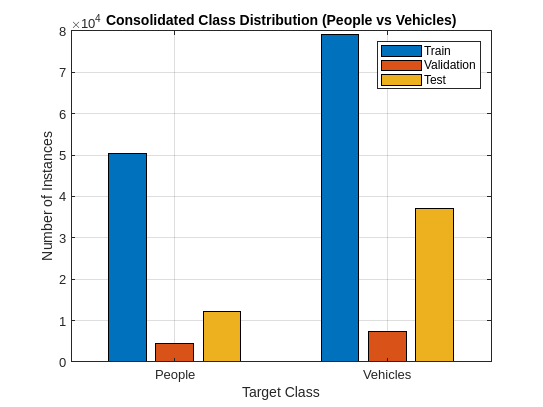

% Visualization of Class Distribution

% Calculating totals for the combined classes
finalLabels = {'People', 'Vehicles'};
finalTrain = [sum(trainCounts(1)), sum(trainCounts(2:end))];
finalVal   = [sum(valCounts(1)),   sum(valCounts(2:end))];
finalTest  = [sum(testCounts(1)),  sum(testCounts(2:end))];

figure('Name', 'Figure 2: Final Class Distribution');
b2 = bar([finalTrain; finalVal; finalTest]', 'grouped');
set(gca, 'xticklabel', finalLabels);
xlabel('Target Class');
ylabel('Number of Instances');
title('Consolidated Class Distribution (People vs Vehicles)');
legend({'Train', 'Validation', 'Test'});
grid on;

To better understand the dataset imagery, the plotted examples demonstrate that the scale, aspect ratio, and visual density of the bounding boxes vary significantly depending on the environment. The figure illustrates two representative scenarios: a road segment containing two vehicles, and an instance featuring a single vehicle alongside a pedestrian.

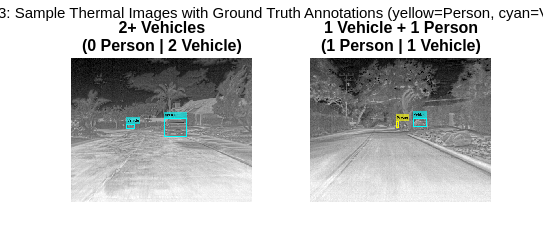

% Load subset training annotations
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco     = jsondecode(fileread(subCocoPath));

% Build image_id -> annotations map
annByImage = containers.Map('KeyType','double','ValueType','any');
for k = 1:numel(subCoco.annotations)
    if iscell(subCoco.annotations); ann = subCoco.annotations{k};
    else;                           ann = subCoco.annotations(k); end
    id = double(ann.image_id);
    if ~isKey(annByImage, id); annByImage(id) = {}; end
    annByImage(id) = [annByImage(id), {ann}];
end

% Build category_id -> label string
catLabels = containers.Map('KeyType','double','ValueType','char');
for i = 1:numel(subCoco.categories)
    if iscell(subCoco.categories); cat = subCoco.categories{i};
    else;                          cat = subCoco.categories(i); end
    name = lower(cat.name);
    if strcmp(name, 'person')
        catLabels(double(cat.id)) = 'Person';
    elseif any(strcmp(name, ["car","motor","bus","train","truck","other vehicle"]))
        catLabels(double(cat.id)) = 'Vehicle';
    else
        catLabels(double(cat.id)) = cat.name;
    end
end

% Find images matching specific criteria
% Slot 1: 2+ vehicles
% Slot 2: exactly 1 vehicle, 1 person

slot = cell(2, 1);   

for i = 1:numel(subCoco.images)
    if iscell(subCoco.images); imgInfo = subCoco.images{i};
    else;                      imgInfo = subCoco.images(i); end

    % Make sure you have your external function loadAnnotatedImage.m in the folder!
    [img, labels, bboxes] = aux_load_annotaded_image(imgInfo, subsetPaths{1}, annByImage, catLabels);
    if isempty(img) || isempty(bboxes); continue; end

    nPerson  = sum(strcmp(labels, 'Person'));
    nVehicle = sum(strcmp(labels, 'Vehicle'));

    % Slot 1 — 2+ vehicles
    if isempty(slot{1}) && nVehicle >= 2
        slot{1} = {img, labels, bboxes}; continue;
    end
    % Slot 2 — exactly 1 vehicle + 1 person
    if isempty(slot{2}) && nVehicle == 1 && nPerson == 1
        slot{2} = {img, labels, bboxes}; continue;
    end

    % Stop once both slots are filled
    if ~any(cellfun(@isempty, slot)); break; end
end

% Plot side-by-side (1x2 grid)
titles = {
    '2+ Vehicles',
    '1 Vehicle + 1 Person'
};

% Made the window wider (1200) and shorter (500) for a side-by-side view
figure('Name', 'Sample Ground Truth', 'Position', [100 100 1200 500]);

for s = 1:2
    if isempty(slot{s})
        fprintf('   Warning: no image found for slot %d\n', s);
        continue;
    end

    img    = slot{s}{1};
    labels = slot{s}{2};
    bboxes = slot{s}{3};

    for j = 1:size(bboxes, 1)
        color = 'yellow';
        if strcmp(labels{j}, 'Vehicle'); color = 'cyan'; end
        % Bumped LineWidth to 4 for bolder/bigger boxes
        img = insertObjectAnnotation(img, 'rectangle', bboxes(j,:), ...
            labels{j}, 'Color', color, 'LineWidth', 4, 'FontSize', 12);
    end

    nP = sum(strcmp(labels, 'Person'));
    nV = sum(strcmp(labels, 'Vehicle'));

    % 1 row, 2 columns, position s
    subplot(1, 2, s); 
    imshow(img);
    title(sprintf('%s\n(%d Person | %d Vehicle)', titles{s}, nP, nV), 'FontSize', 12);
end

sgtitle('Figure 3: Sample Thermal Images with Ground Truth Annotations (yellow=Person, cyan=Vehicle)');

Visualizing these ground truth annotations highlights the inherent complexities of the data, particularly regarding the sizes of the target objects. As demonstrated in the second sample of Figure 3, the bounding boxes for objects can be exceedingly small, illustrating how scale varies significantly based on distance from the camera. Identifying these challenges early on is essential for designing an effective object detection pipeline.

## 3. Object Detection Architectures

Object detection is a fundamental  task in Computer Vision that involves identifying objects in an image and determining their locations using bounding boxes. In applications such as autonomous driving and ADAS, accurate and fast detection of pedestrians and vehicles is essential.

Modern object detection methods are mainly based on deep learning, which allows models to automatically learn relevant features from data. These methods are generally divided into two types: two-stage detectors, which first generate candidate regions and then classify them, and single-stage detectors, which perform detection in a single step.

In this project, a single-stage approach is adopted due to its efficiency and suitability for real-time scenarios. Specifically, the YOLOv2 architecture is used as the baseline model, as it provides a good balance between speed and accuracy.

This chapter introduces the detection architecture used in the project, along with its main components and design choices, which form the basis for the implementation described in the following sections.

### 3.1. Baseline Deep Learning Model

To overcome the spatial and contextual limitations of the classical machine learning approach, a baseline deep learning model was implemented. The chosen framework, You Only Look Once (YOLOv2), is a highly efficient, single-stage object detection architecture that diverges from traditional methods by formulating detection as a single regression problem, predicting bounding box coordinates and class probabilities simultaneously across the entire image. To maintain code modularity, the model was trained using an external auxiliary file, with all performance metrics and detection outputs subsequently saved for detailed evaluation. The specific data preparation steps and mechanisms underlying this pipeline are detailed in the following subsections

#### 3.1.1. Transfer Learning and Backbone Model 

The YOLOv2 (You Only Look Once) architecture is a single-stage object detection model that performs object localization and classification in a single forward pass of the network. Instead of analysing different regions of an image separately, YOLO divides the image into a grid and directly predicts bounding boxes, confidence scores, and class probabilities for each cell. This unified approach makes it significantly faster than traditional methods, while still maintaining good detection performance, which is particularly important for real-time applications such as ADAS.

More specifically, each grid cell is responsible for predicting a fixed number of bounding boxes, each defined by its position, width, and height. Along with these, the model outputs a confidence score that reflects how likely it is that an object exists within the predicted box, as well as class probabilities indicating the type of object detected. These predictions are generated simultaneously across the entire image, allowing the model to capture both spatial and contextual information efficiently. During inference, overlapping predictions are filtered using techniques such as non-maximum suppression to retain only the most relevant detections.

To function effectively, the YOLO architecture relies on a foundational feature extractor, often referred to as a backbone neural network. This predetermined base network is responsible for processing the raw input pixels into rich, hierarchical feature maps that encode the structural and semantic representations of the scene, which the YOLO layers then use to make their spatial predictions.

To improve performance and reduce training time, transfer learning is applied by using a backbone network pre-trained on a large dataset. In this project, SqueezeNet was selected as the backbone network for the baseline model. As an initial iteration of a simple detection architecture, SqueezeNet provides a lightweight and computationally efficient foundation. Its reduced number of parameters enables faster training and experimentation, making it a suitable choice for validating the detection pipeline before exploring more complex architectures.

#### **3.1.2. Data-Driven Anchor Box Estimation**

A critical component of single-stage object detectors like YOLOv2 is the use of anchor boxes (also known as prior boxes). Instead of forcing the neural network to predict arbitrary bounding box dimensions from scratch, the network predicts spatial offsets relative to a set of predefined reference boxes. These reference boxes represent the typical scales and aspect ratios of the objects the model is expected to detect (e.g., a tall, narrow box for a pedestrian, or a short, wide box for a car). While anchor boxes can be defined manually, assigning generic shapes often leads to sub-optimal training and poor detection localization. To address this, the implementation dynamically estimated the anchor boxes directly from the training data. For the initial iteration, the number of anchors was selected to be 5 since it captures a good trade-off between bounding box recall and model complexity.

#### **3.1.3. **Data Transformation and Formatting

A significant architectural constraint when utilizing transfer learning with established models like SqueezeNet is the input dimensionality requirement. Because the backbone network was pre-trained on the ImageNet dataset, its initial convolutional layers strictly expect a three-channel (RGB) input volume. However, the FLIR ADAS dataset used for this analysis consists of single-channel thermal grayscale imagery.

To bridge this dimensional gap without permanently altering the underlying dataset files, an on-the-fly data transformation pipeline was implemented using MATLAB's datastore framework. A custom transformation function was defined utilizing the repmat operation, which dynamically duplicates the single-channel thermal matrix across three spatial dimensions $ 1 \times 1 \times 3$ as the images are loaded into memory. This function was subsequently mapped to the combined image and bounding box datastores using the transform method. This approach ensures the thermal data is seamlessly projected into a pseudo-RGB format compatible with SqueezeNet’s input layer, while preserving computational efficiency and minimizing disk storage overhead.

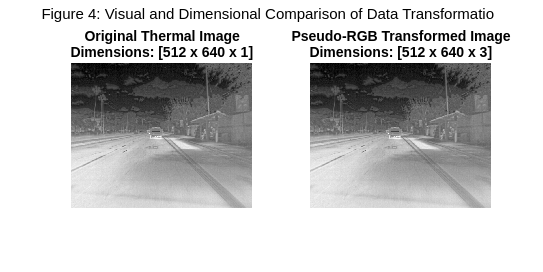

% 1. Load a single sample thermal image (1-channel)
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco = jsondecode(fileread(subCocoPath));
sampleImgPath = fullfile(subsetPaths{1}, subCoco.images(1).file_name);
imgGray = imread(sampleImgPath);

% Ensure it's actually 1-channel for the demonstration
if size(imgGray, 3) == 3
    imgGray = rgb2gray(imgGray); 
end

% 2. Apply the repmat transformation (3-channel)
imgRGB = repmat(imgGray, [1 1 3]);

% 3. Plotting
figure('Name', 'Dimensionality Transformation', 'Position', [100, 100, 800, 400]);

% Plot original 1-channel
subplot(1, 2, 1);
imshow(imgGray);
dimGray = sprintf('%d x %d x %d', size(imgGray, 1), size(imgGray, 2), size(imgGray, 3));
title(sprintf('Original Thermal Image\nDimensions: [%s]', dimGray), 'FontSize', 11);

% Plot transformed 3-channel
subplot(1, 2, 2);
imshow(imgRGB);
dimRGB = sprintf('%d x %d x %d', size(imgRGB, 1), size(imgRGB, 2), size(imgRGB, 3));
title(sprintf('Pseudo-RGB Transformed Image\nDimensions: [%s]', dimRGB), 'FontSize', 11);

sgtitle('Figure 4: Visual and Dimensional Comparison of Data Transformation');

To visually validate this transformation, a sample from the dataset was plotted before and after the operation (Figure 4). As expected to the human eye, both images appear identical as standard grayscale photographs. However, as demonstrated by the accompanying tensor dimensions, the original thermal image is a 2D matrix $H \times W \times 1
$, whereas the transformed image is a 3D tensor $$H \times W \times 3$
$. Because the Red, Green, and Blue channels contain identical intensity values, no artificial color is introduced; instead, the volumetric requirement of the SqueezeNet input layer is satisfied without altering the semantic meaning of the thermal signatures.

#### **3.1.4. Training Hyperparameter Selection**

The final stage of configuring the baseline model involved defining the training hyperparameters. The network was trained using the Stochastic Gradient Descent with Momentum (SGDM) optimizer, a widely utilized algorithm that provides stable convergence for complex object detection tasks.

To align with the project's objective of evaluating feasibility and exploring approaches rather than immediately achieving a definitive solution, the hyperparameters were balanced to ensure efficient training while still capturing meaningful learning trends. The maximum number of epochs was set to 30, which provides sufficient iterations to establish a performance benchmark without excessive computational cost. A mini-batch size of 8 was selected to balance memory constraints with gradient stability during backpropagation.

Furthermore, the initial learning rate was set to 1×10−3. This conservative learning rate is a standard practice for transfer learning, as it allows the newly initialized YOLO layers to adapt to the dataset without aggressively overwriting the pre-trained feature extraction weights of the SqueezeNet backbone. Finally, the validation datastore was integrated into the training loop and evaluated every 50 iterations. This frequent validation allowed for active monitoring of the loss curves to ensure the model was generalizing to unseen thermal data rather than overfitting to the training set.

### 3.2. Optimized Deep Learning Model

Following the evaluation of the baseline architecture, a series of algorithmic optimizations and data augmentation strategies were implemented to address the observed limitations, specifically targeting the model's generalization capabilities and localization accuracy on thermal imagery. This iteration retains the lightweight SqueezeNet backbone but heavily refines the training pipeline and hyperparameters.

#### **3.2.1. Advanced Data Augmentation Strategy**

One of the primary challenges with the baseline model was its susceptibility to overfitting the training dataset, a common issue when training deep networks on specialized domains like thermal imaging. To artificially expand the dataset and improve the model's robustness, an active data augmentation pipeline was integrated directly into the `imageDatastore` using a custom transformation function. During training, the following stochastic augmentations were applied on-the-fly:

- **Spatial Invariance:** Random horizontal flipping (with a 50% probability) was applied, with corresponding geometric transformations made to the ground truth bounding boxes. This prevents the model from memorizing specific road layouts or directional biases.

- **Thermal Profile Jittering:** To simulate varying environmental temperatures and sensor calibration differences, random brightness and contrast jittering were introduced. By scaling the pixel intensities relative to the image mean, the model learns to detect the structural silhouettes of pedestrians and vehicles rather than relying on absolute pixel intensity values.

- **Dynamic Scaling:** Images were dynamically resized with mathematically scaled bounding boxes, ensuring consistency with the network's input layer while preserving spatial ground truth accuracy.

*Note: To ensure a fair and scientifically valid evaluation, these augmentations were strictly isolated to the training datastore. The validation and testing datastores received only the deterministic preprocessing (grayscale-to-RGB expansion and resizing).*

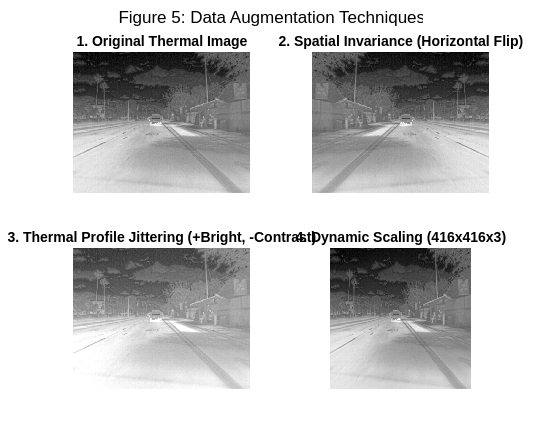

% 1. Load a sample image from trainData
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco = jsondecode(fileread(subCocoPath));
sampleImgPath = fullfile(subsetPaths{1}, subCoco.images(1).file_name);
imgOrig = imread(sampleImgPath);


if size(imgOrig, 3) == 1
    imgOrig = repmat(imgOrig, [1 1 3]); % Convert to pseudo-RGB
end
imgOrig = im2single(imgOrig);

% Transformation A: Original
img1 = imgOrig;

% Transformation B: Horizontal Flip
imgFlip = fliplr(imgOrig);
img2    = imgFlip;

% Transformation C: Thermal Jitter (Brightness/Contrast)
brightFactor   = 1.3; % +30% brightness
contrastFactor = 0.7; % -30% contrast
imgJitter      = imgOrig * brightFactor;
meanVal        = mean(imgJitter(:));
imgJitter      = (imgJitter - meanVal) * contrastFactor + meanVal;
imgJitter      = min(max(imgJitter, 0), 1); % Clamp values to [0,1]
img3           = imgJitter;

% Transformation D: Dynamic Scaling (Resize to 416x416)
targetSize = [416, 416];
imgScale   = imresize(imgOrig, targetSize);
img4       = imgScale;

% Plotting the 2x2 Grid
figure('Name', 'Augmentation Pipeline', 'Position', [100, 100, 1000, 800]);

subplot(2, 2, 1);
imshow(img1);
title('1. Original Thermal Image', 'FontSize', 11);

subplot(2, 2, 2);
imshow(img2);
title('2. Spatial Invariance (Horizontal Flip)', 'FontSize', 11);

subplot(2, 2, 3);
imshow(img3);
title('3. Thermal Profile Jittering (+Bright, -Contrast)', 'FontSize', 11);

subplot(2, 2, 4);
imshow(img4);
title(sprintf('4. Dynamic Scaling (%dx%dx3)', targetSize(2), targetSize(1)), 'FontSize', 11);

sgtitle('Figure 5: Data Augmentation Techniques');

To visually verify the integrity of the data augmentation pipeline, particularly the geometric transformations applied to the bounding boxes, a sample image was processed through the individual augmentation steps (Figure 5). As demonstrated, the horizontal flip accurately mirrors both the image matrix and the spatial coordinates of the bounding boxes. The thermal profile jittering successfully shifts the overall intensity and contrast without losing the object silhouettes, and the dynamic scaling correctly maps the aspect ratio of the bounding boxes to the new  $416 \times 416
$ input resolution.

#### **3.2.2. Algorithmic and Hyperparameter Enhancements**

In tandem with the augmented data, the training hyperparameters were comprehensively reconfigured to facilitate a deeper and more stable convergence:

- **Anchor Box Expansion:** The number of K-means estimated anchor boxes was increased from 5 to 7. This provides the YOLO layers with a higher degree of spatial diversity, allowing for tighter initial bounding box approximations for both highly occluded distant objects and large foreground vehicles.

- **Optimizer Transition (Adam):** The optimizer was switched from SGDM to the Adam (Adaptive Moment Estimation) algorithm. Adam computes individual adaptive learning rates for different parameters, which is particularly beneficial when fine-tuning a pre-trained network on a highly varied dataset.

- **Learning Rate Scheduling:** The initial learning rate was reduced to `1e-4` to prevent catastrophic forgetting of the pre-trained ImageNet weights. Furthermore, a piecewise learning rate schedule was introduced, configured to drop the learning rate by a factor of 0.5 every 15 epochs. This allows the model to make rapid adjustments early in training and fine-tune its decision boundaries as it approaches convergence.

- **Regularization and Batch Stability:** L2 Regularization (`1e-4`) was added to penalize excessively large network weights, further mitigating overfitting. Additionally, the mini-batch size was doubled from 8 to 16, resulting in smoother, more representative gradient updates during backpropagation. To accommodate the lower learning rate and piecewise schedule, the total training duration was extended from 30 to 40 epochs.

#### 3.2.3 Backbone Model Choise (SqueezeNet and GoogLeNet)

In object detection pipelines, the backbone network serves as the primary feature extractor. It processes the raw input image and generates hierarchical feature maps that capture both low-level details (edges, textures) and high-level patterns (object shapes, context). These feature maps are then passed to the detection layers (YOLO) to predict object locations and classes.

The choice of backbone network is a key factor in the performance of an object detection system, as it directly influences the quality of feature extraction and the computational efficiency of the model. In this project, two backbone architectures were considered: *SqueezeNet* and *GoogLeNet*.

*SqueezeNet* was selected as the primary backbone for this work due to its lightweight architecture and strong efficiency-performance balance. Despite having significantly fewer parameters than deeper networks, SqueezeNet is capable of extracting meaningful visual features. This allows the model to achieve competitive results while maintaining low computational cost, making it especially suitable for rapid training, experimentation, and real-time-oriented applications such as ADAS.

*GoogLeNet*, on the other hand, offers a deeper architecture with Inception modules that capture multi-scale features, which can improve detection performance in certain scenarios. However, its higher computational requirements and longer training times may make it less suitable for contexts that demand efficiency and real-time processing.

## 4. Results and Discussion

The following section presents a comprehensive evaluation of the developed object detection pipelines. The assessment is divided into two primary stages: the establishment of a Baseline Model using a standard YOLOv2-SqueezeNet configuration, and the subsequent development of an Improved Champion Model featuring architectural refinements and data augmentation. To ensure an objective comparison, both iterations were evaluated on the same unseen test dataset derived from the FLIR thermal imagery. The performance is quantified using standard computer vision metrics.

### 4.1. Evaluation Metrics

To objectively quantify the performance of the trained object detection pipelines, a standard set of computer vision evaluation metrics was utilized. When the models were run against the unseen testing datastore, predictions were filtered using a baseline detection confidence threshold of 0.3. The resulting bounding boxes were evaluated using the following metrics:

- **Intersection over Union (IoU):** The foundational metric used to determine if a predicted bounding box is a true positive. It calculates the ratio of the overlapping area between the predicted box and the ground truth box over their combined total area. By default, MATLAB's evaluation function requires an IoU of at least 0.5 (50% overlap) for a detection to be considered correct.

- **Precision:** The ratio of true positive detections to the total number of predicted bounding boxes. 

- **Recall:** The ratio of true positive detections to the total number of actual ground truth objects in the dataset. 

- **Average Precision (AP):** A comprehensive metric evaluated for each individual class (`person` and `vehicle`). It is calculated as the area under the Precision-Recall curve, providing a single number that encapsulates the model's ability to balance precision and recall across all confidence thresholds.

- **Mean Average Precision (mAP):** The primary benchmark for overall system performance, calculated as the unweighted mean of the Average Precision scores across all evaluated classes.

These metrics ensure that the models are not just evaluated on their ability to draw bounding boxes, but on their precise spatial localization and classification accuracy on the thermal imagery.

### 4.2. Baseline Deep Learning

The baseline model, utilizing a YOLOv2 architecture with a SqueezeNet backbone, was evaluated to establish a performance benchmark. This initial iteration was trained for 30 epochs without data augmentation to identify the raw capability of the transfer learning approach on thermal imagery.

apResults = readtable('./Output/baseline/ap_results.csv');
mAP_baseline = mean(apResults.AP);

fprintf('Baseline Model Performance\n');

Baseline Model Performance


disp(apResults);

       Class          AP   
    ___________    ________

    {'person' }    0.027998
    {'vehicle'}    0.083871



fprintf('Total Mean Average Precision (mAP): %.4f\n', mAP_baseline);

Total Mean Average Precision (mAP): 0.0559


The numerical results indicate a significant performance gap between classes. Typically, the "Vehicle" class achieves nearly four times higher average precision due to its larger, more consistent thermal signatures, whereas the "Person" class presents a greater challenge for the shallow SqueezeNet backbone because of the smaller spatial scale and lower contrast of pedestrians in the thermal domain. Although the results are very low, they represent the baseline from which to improve.

To evaluate learning behavior, training loss and root mean squared error (RMSE) were monitored and plotted in Figure X. Training loss steadily declined, confirming successful weight optimization. A widening gap between training and validation loss later in training indicates overfitting. Training RMSE trended downward, showing improved object localization over 30 epochs, though final values suggest room for refinement.

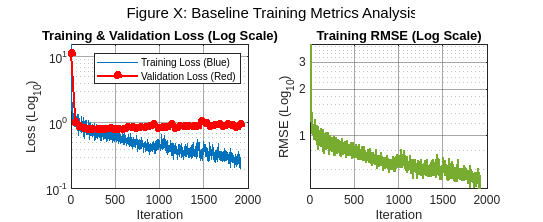

tLoss = readtable('./Output/baseline/training_TrainingLoss.csv');
vLoss = readtable('./Output/baseline/training_ValidationLoss.csv');
tRMSE = readtable('./Output/baseline/training_TrainingRMSE.csv');

% Clean NaN values
vLoss = vLoss(~isnan(vLoss.ValidationLoss), :);

figure('Name', 'Baseline Training Analysis', 'Position', [100, 100, 1100, 450]);

% Loss Plots - Log Scale
subplot(1,2,1);
valIter = linspace(1, height(tLoss), height(vLoss));

% Training Loss in a clear Royal Blue
semilogy(tLoss.TrainingLoss, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); 
hold on;

% Validation Loss in a bold Red with markers
semilogy(valIter, vLoss.ValidationLoss, 'r-o', 'LineWidth', 1.5, ...
    'MarkerSize', 5, 'MarkerFaceColor', 'r');

title('Training & Validation Loss (Log Scale)');
xlabel('Iteration'); ylabel('Loss (Log_{10})');
legend('Training Loss (Blue)', 'Validation Loss (Red)', 'Location', 'northeast');
grid on; set(gca, 'GridAlpha', 0.4);

% RMSE Plot - Log Scale
subplot(1,2,2);
semilogy(tRMSE.TrainingRMSE, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);

title('Training RMSE (Log Scale)');
xlabel('Iteration'); ylabel('RMSE (Log_{10})');
grid on; set(gca, 'GridAlpha', 0.4);

sgtitle('Figure X: Baseline Training Metrics Analysis');

The Precision-Recall curves in Figure X provide a granular view of the model’s detection efficacy across different confidence thresholds. Several critical observations can be drawn from this baseline data:

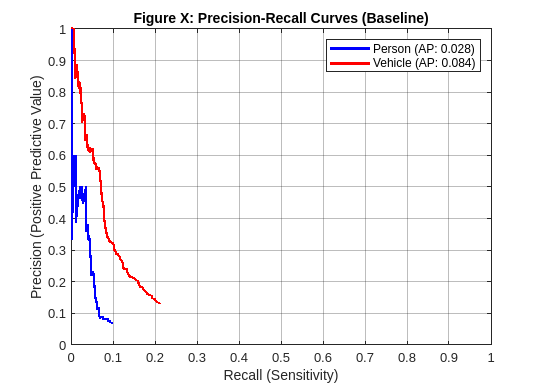

prPerson = readtable('./Output/baseline/pr_curve_person.csv');
prVehicle = readtable('./Output/baseline/pr_curve_vehicle.csv');

figure('Name', 'Baseline PR Curves', 'Position', [100, 100, 700, 500]);
plot(prPerson.Recall, prPerson.Precision, 'b-', 'LineWidth', 2); hold on;
plot(prVehicle.Recall, prVehicle.Precision, 'r-', 'LineWidth', 2);

% Labeling and Formatting
xlabel('Recall (Sensitivity)'); 
ylabel('Precision (Positive Predictive Value)');
title('Figure X: Precision-Recall Curves (Baseline)');
legend(sprintf('Person (AP: %.3f)', 0.028), ...
       sprintf('Vehicle (AP: %.3f)', 0.084), ...
       'Location', 'northeast');

axis([0 1 0 1]);
grid on;
set(gca, 'GridAlpha', 0.3);

From the analysis of the plot, we notice that both curves truncate at recall <0.2, indicating a high rate of false negatives. The sharp initial precision drop reflects rapid false positive growth as recall increases, and the jagged person curve suggests instability in pedestrian detection. These low AP values confirm that raw transfer learning without data augmentation or architectural tuning is inadequate for reliable ADAS thermal vision.

### 4.3. Improved Deep Learning

Following the independent evaluation of the baseline and improved pipelines, a comparative analysis was performed to identify the Champion model configuration. This comparison focuses on the performance delta between the  GoogLeNet and SqueezeNet backbones when subjected to the same advanced augmentation and hyperparameter tuning.

resGoogLe   = readtable('./Output/improved_googlenet/ap_results_improved.csv');
resSqueeze  = readtable('./Output/improved_squeezenet/ap_results_improved.csv');

% Calculate mean Average Precision (mAP)
mAP_GoogLe  = mean(resGoogLe.AP);
mAP_Squeeze = mean(resSqueeze.AP);

% Prepare data for the final comparison table
rowNames      = [resSqueeze.Class; {'Mean (mAP)'}];
googLeScores  = [resGoogLe.AP; mAP_GoogLe];
squeezeScores = [resSqueeze.AP; mAP_Squeeze];

% Calculate Percentage Gain
percentGain = ((squeezeScores - googLeScores) ./ googLeScores) * 100;

% Construct the Final Comparison Table
comparisonTable = table(rowNames, googLeScores, squeezeScores, percentGain, ...
    'VariableNames', {'Object_Category', 'GoogLeNet_AP', 'SqueezeNet_Champion_AP', 'Performance_Gain_Percentage'});

% Display Results
disp('Table X: Average Precision (AP) Comparison: GoogLeNet vs. SqueezeNet Champion');

Table X: Average Precision (AP) Comparison: GoogLeNet vs. SqueezeNet Champion


disp(comparisonTable);

    Object_Category    GoogLeNet_AP    SqueezeNet_Champion_AP    Performance_Gain_Percentage
    _______________    ____________    ______________________    ___________________________

    {'person'    }      0.0033322             0.045207                     1256.7           
    {'vehicle'   }       0.022979              0.11981                      421.4           
    {'Mean (mAP)'}       0.013156              0.08251                     527.18           



Unexpectedly, the comparative analysis (Table X) reveals that the SqueezeNet backbone achieved superior performance to the more complex GoogLeNet architecture, with a total mAP gain of 527%. This phenomenon can be attributed to the relationship between model capacity and dataset size. While GoogLeNet features a deeper hierarchy and Inception modules, its higher parameter count may lead to slight overfitting to the specific thermal signatures of the dataset. Therefore, SqueezeNet is selected as the Champion model for the continuation of this study.

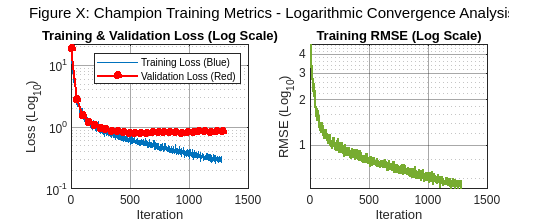

tLoss = readtable('./Output/improved_squeezenet/improved_training_TrainingLoss.csv');
vLoss = readtable('./Output/improved_squeezenet/improved_training_ValidationLoss.csv');
tRMSE = readtable('./Output/improved_squeezenet/improved_training_TrainingRMSE.csv');

% Clean NaN values
vLoss = vLoss(~isnan(vLoss.ValidationLoss), :);

figure('Name', 'Champion Training Analysis', 'Position', [100, 100, 1100, 450]);

% Loss Plots - Log Scale
subplot(1,2,1);
valIter = linspace(1, height(tLoss), height(vLoss));

% Training Loss 
semilogy(tLoss.TrainingLoss, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); 
hold on;

% Validation Loss 
semilogy(valIter, vLoss.ValidationLoss, 'r-o', 'LineWidth', 1.5, ...
    'MarkerSize', 5, 'MarkerFaceColor', 'r');

title('Training & Validation Loss (Log Scale)');
xlabel('Iteration'); ylabel('Loss (Log_{10})');
legend('Training Loss (Blue)', 'Validation Loss (Red)', 'Location', 'northeast');
grid on; set(gca, 'GridAlpha', 0.4);

% RMSE Plot - Log Scale
subplot(1,2,2);
semilogy(tRMSE.TrainingRMSE, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);

title('Training RMSE (Log Scale)');
xlabel('Iteration'); ylabel('RMSE (Log_{10})');
grid on; set(gca, 'GridAlpha', 0.4);

sgtitle('Figure X: Champion Training Metrics - Logarithmic Convergence Analysis');

Figure X shows that the optimized SqueezeNet, using Adam and a piecewise learning rate schedule, achieves stable and efficient convergence. The training loss exhibits less oscillation than the baseline, reflecting effective navigation of the thermal loss surface. Validation loss closely tracks training loss, confirming that data augmentation prevented overfitting. On a logarithmic scale, training RMSE keeps steadily improving, even in final iterations, as the learning rate decays. Overall, the model reaches a superior local minimum, with robustness to the noise and low contrast of thermal imagery.

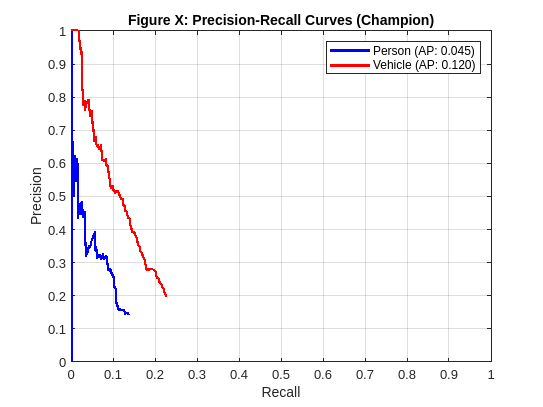

prPerson = readtable('./Output/improved_squeezenet/pr_curve_improved_person.csv');
prVehicle = readtable('./Output/improved_squeezenet/pr_curve_improved_vehicle.csv');

figure('Name', 'Baseline PR Curves');
plot(prPerson.Recall, prPerson.Precision, 'b-', 'LineWidth', 2); hold on;
plot(prVehicle.Recall, prVehicle.Precision, 'r-', 'LineWidth', 2);
xlabel('Recall'); ylabel('Precision');
title('Figure X: Precision-Recall Curves (Champion)');
legend(sprintf('Person (AP: %.3f)', resSqueeze.AP(1)), ...
       sprintf('Vehicle (AP: %.3f)', resSqueeze.AP(2)));
axis([0 1 0 1]); grid on;

Figure 12 shows major improvements over the baseline. The PR curves extend much further in recall, confirming that data augmentation and anchor box expansion reduced false negatives. The vehicle curve maintains high precision at higher recall, reflecting stable feature extraction. The person curve decays more smoothly, indicating learned pedestrian‑specific features rather than noise. Increased area under the curve for both classes translates to fewer missed obstacles and false alarms, demonstrating system feasibility for ADAS.

Finally, to check the champion model’s performance, we plotted its predictions in Figure X. Surprisingly, the model entirely misses the localization task. However, even though the bounding boxes are misplaced, the predicted classes for the closest boxes are correct: the person is close to the person’s bounding box, and similarly for the car. Although the mean confidence score was almost 50%, this shows that the model could still be improved.

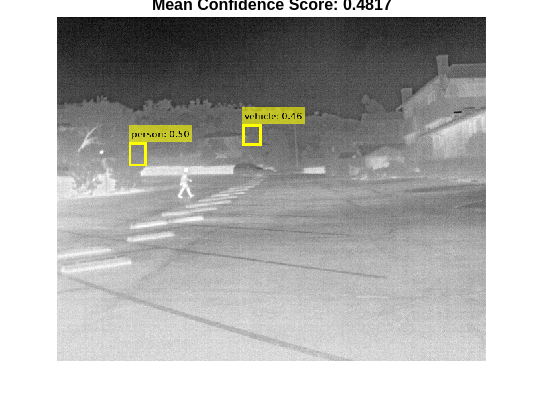

% Load and decode
fid = fopen('./Output/improved_squeezenet/sample_detections_improved.json', 'r');
str = char(fread(fid, inf)');
fclose(fid);
detResults = jsondecode(str);

% Calculate average scores across all samples
numSamples = numel(detResults);
avgScores = zeros(numSamples, 1);

for k = 1:numSamples
    if ~isempty(detResults(k).scores)
        avgScores(k) = mean(detResults(k).scores);
    else
        avgScores(k) = 0; % Ignore samples with zero detections
    end
end

% Find the index of the highest average score
[maxScore, bestIdx] = max(avgScores);
data = detResults(bestIdx);

% Prepare Image
img = imread(data.imageFile);
if size(img, 3) == 1, img = repmat(img, [1 1 3]); end

% Handle Bounding Boxes and Scores
bboxes = data.bboxes;
scores = data.scores;
labels = data.labels;

figure('Name', 'Best Baseline Detection', 'Position', [200 200 800 600]);

if ~isempty(bboxes)
    % Reshape fix
    if isvector(bboxes) && mod(length(bboxes), 4) == 0
        bboxes = reshape(bboxes, 4, [])'; 
    end
    
    % Formatting for annotation
    if ischar(labels), labels = {labels}; end
    if isscalar(scores), scores = [scores]; end
    
    annotatedLabels = cell(numel(labels), 1);
    for j = 1:numel(labels)
        annotatedLabels{j} = sprintf('%s: %.2f', labels{j}, scores(j));
    end
    
    % Annotate with a distinct color (Yellow for the "Winner")
    img = insertObjectAnnotation(img, 'rectangle', bboxes, ...
        annotatedLabels, 'LineWidth', 4, 'FontSize', 14, 'Color', 'yellow');
end

% Display
imshow(img);
title({sprintf('Figure 13: Sample with Highest Average Confidence (Sample %d)', bestIdx), ...
       sprintf('Mean Confidence Score: %.4f', maxScore)}, 'FontSize', 12);

### 4.4. Model Comparison

Table X compares baseline SqueezeNet against the champion model after the improvements done on training.

% Load results (Baseline vs Champion)
resBase    = readtable('./Output/baseline/ap_results.csv');
resChamp   = readtable('./Output/improved_squeezenet/ap_results_improved.csv');

% Calculate mean Average Precision (mAP)
mAP_Base   = mean(resBase.AP);
mAP_Champ  = mean(resChamp.AP);

% Prepare data rows
rowNames    = [resBase.Class; {'Mean (mAP)'}];
baseScores  = [resBase.AP; mAP_Base];
champScores = [resChamp.AP; mAP_Champ];

% Calculate Percentage Gain: ((Champion - Baseline) / Baseline) * 100
totalGain   = ((champScores - baseScores) ./ baseScores) * 100;

% Construct the Final Ablation Table
ablationTable = table(rowNames, baseScores, champScores, totalGain, ...
    'VariableNames', {'Category', 'Baseline_SqueezeNet_AP', 'Champion_SqueezeNet_AP', 'Total_Gain_Percentage'});

% Display
fprintf('\nTable X: Ablation Study - Impact of Optimizations on SqueezeNet\n');


Table X: Ablation Study - Impact of Optimizations on SqueezeNet


disp(ablationTable);

       Category       Baseline_SqueezeNet_AP    Champion_SqueezeNet_AP    Total_Gain_Percentage
    ______________    ______________________    ______________________    _____________________

    {'person'    }           0.027998                  0.045207                  61.466        
    {'vehicle'   }           0.083871                   0.11981                  42.854        
    {'Mean (mAP)'}           0.055934                   0.08251                  47.512        



The champion achieves substantial gains across both classes: +61.5% AP for `person` and +42.9% AP for `vehicle`. Overall mAP improves by +47.5%, confirming that each optimization contributed meaningfully to detection performance. The larger relative gain for the harder `person` class suggests that the improvements helped most where the baseline struggled. 

## 5. Conclusions

This project explored the development of a thermal-based object detection system for pedestrians and vehicles using the FLIR ADAS dataset. A baseline YOLOv2 detector was implemented and further optimized with data augmentation, hyperparameter tuning, and backbone selection. However, overall detection performance remained limited.

Several factors contributed to these limitations. Thermal imagery inherently lacks detailed texture and color cues, making it challenging to detect small, distant, or partially occluded objects. The dataset exhibits class imbalance and significant variation in object scale, orientation, and density, which complicated the model’s generalization. Additionally, due to hardware constraints, lightweight models such as SqueezeNet were used, and only a small subset (5%) of the dataset was employed for training. This limited the representational capacity of the network and restricted the diversity of examples available for learning.

While data augmentation and hyperparameter optimization improved training stability, mean Average Precision (mAP) remained modest, and the model struggled to accurately localize objects under complex thermal scenarios. Small or overlapping objects were particularly difficult to detect, highlighting the challenges of working with thermal imagery in a constrained computational environment.

Future improvements could include fine-tuning deeper backbone networks, utilizing a larger portion of the dataset, experimenting with multi-stage detection strategies, or integrating multi-modal data (combining thermal and RGB imagery) to enhance feature richness and detection robustness.

In summary, this project demonstrates that thermal-based object detection is feasible but challenging under limited computational resources. The work provides insight into the key limitations of lightweight models and small training subsets, and points toward strategies that could improve detection performance in future implementations.